mu = 0.0010014; %dynamisk viscusitet
rho = 1000; %kg/m^3
d = 0.1; %m
Re = 100;


U = Re * mu / (rho * d)

U = 0.0010

format longg
% Define the filename and sheetname
filename = 'CFD_Data.xlsx';
sheetname = 'Plot Data';

% Import data from Excel file
[numericData, textData, rawData] = xlsread(filename, sheetname);

% Extract the desired range of data
% rowRange = 5:size(rawData, 1);
% colRange = [2, 3, 5, 6, 8, 9]; % Columns B, C, E, F, H, I

% Extract numeric data from specified range
% numericData = cell2mat(rawData(rowRange, colRange))

v_mesh_3 = numericData(:,2)

v_mesh_3 =        0.00100812604486232
       0.00101662302933711
       0.00102510095956175
       0.00103360311894736
       0.00104239624969479
       0.00105803190862506
       0.00107604251878836
       0.00109462548133736
       0.00111308789695917
       0.00113128253533754



v_mesh_5 = numericData(:,5)

v_mesh_5 =        0.00102008724165938
       0.00103596361096638
       0.00105339301761453
       0.00107030566458811
       0.00108720521717432
        0.0011153349468618
       0.00114534551524809
       0.00117300765096994
       0.00119912837120973
       0.00122393054228391


v_mesh_7 = numericData(:,8)

v_mesh_7 =        0.00102914473857032
       0.00103818472210025
       0.00105053624342351
       0.00106555323915951
       0.00108003717553709
        0.0011028318204015
       0.00112687606516927
       0.00115005154987176
       0.00117203142593108
       0.00119138374526123



forskel_57 = max(v_mesh_5)/max(v_mesh_7)

forskel_57 =          0.986203104239441


forskel_75 = max(v_mesh_7)/max(v_mesh_5)

forskel_75 =           1.01398991313376


filename = 'Velocity.xlsx';
sheetname = 'Plot Data';

syms u(y) y

% Import data from Excel file
[numericData, textData, rawData] = xlsread(filename, sheetname);
Y = numericData(:,1)

Y =                    0
   0.004982375437011
   0.009964750874021
   0.014947126311032
   0.019929501748043
   0.024911877185054
   0.029894252622065
   0.034876628059075
   0.039859003496086
   0.044841378933097


u_sw = numericData(:,2)

u_sw =    0.001945101940550
   0.001925757708681
   0.001872063225719
   0.001782550031606
   0.001655118710774
   0.001487684240461
   0.001272929672980
   0.001015113952433
   0.000714502592478
   0.000374133210515


U = 0.0010;
mu = 0.0010014;
R = 0.050; %mm radius
% u(y) = 1/(4*mu) * 8*mu * u_sw / R^2 * (R^2 - y^2) 

% u_sol = 1/(4*mu) * 8*mu * U / R^2 .* (R^2 - Y.^2) 

u_sol =    0.040000000000000
   0.036014099650391
   0.032028199300783
   0.028042298951174
   0.024056398601566
   0.020070498251957
   0.016084597902348
   0.012098697552740
   0.008112797203131
   0.004126896853523


u_sol = 1/(4*mu) * 8*mu * U / R^2 .* (R^2 - Y.^2) 

procent_afvigelse = max(u_sol)/max(u_sw)

procent_afvigelse =   20.564474882323182


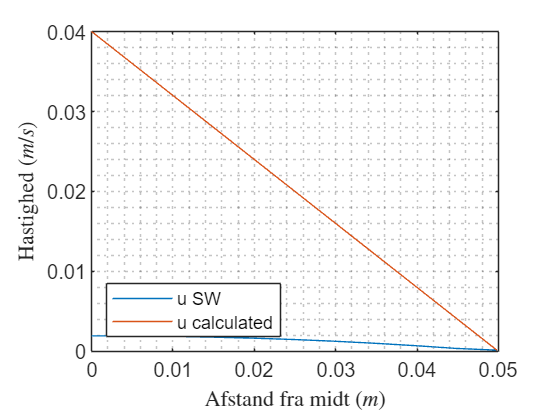


plot(Y, u_sw, 'DisplayName','u SW')
hold on
plot(Y, u_sol, 'DisplayName','u calculated')
xlabel('Afstand fra midt $(m)$', 'Interpreter','latex')
ylabel('Hastighed $(m/s)$', 'Interpreter','latex')
grid('minor')
legend('Location','southwest')
hold off

U=max(max(u_sw))

U =    0.001945101940550


dPdx = 8*mu*U/R^2

dPdx =    0.006233040266454


dPdx = 8*mu*U/R^2 * 0.45

dPdx =    0.002804868119904


dPdx_SW = 0.002333225

dPdx_SW =    0.002333225000000



(dPdx_SW-dPdx)/dPdx_SW

ans =   -0.202142150844539



U=max(max(u_sol))

U =    0.040000000000000


dPdx_cal = 8*mu*U/R^2

dPdx_cal =    0.128179200000000



dPdx/dPdx_cal

ans =    0.021882396831188


% dPdx_cal = 0.002333225
U = 0.0010;
dPdx = 8*mu*U/R^2

dPdx =    0.003204480000000


dPdx_SW = 0.0014

dPdx_SW =    0.001400000000000



dPdx/dPdx_cal

ans =    0.025000000000000
